# Tarea Semanal 7

## TS6 - M7.1

Tabla de diferencias divididas

x=[2 4 5];
y=[3 2 1];

diff(y);

difdiv2(x,y)

ans =    -0.1667
         0
         0


## TS6 - M7.2

Newtoncoeff

x= [-2 1 4 -1 3 -4]'; %vector x en columna..completar
y= [-1 2 59 4 24 -53]'; %vector y en columna..completar
a= newtoncoeff(x, y)%encuentra coef en columna...completar
s= sum(a) %almacena la suma de los coeficientes del polinomio interpolador
p= newtonpoly(a, x, 2)   %p almacena el polinomio evaluado en 2...completar
%%%%%%%%funciones a usar%%%%%%%%%%%%%

function a=newtoncoeff(x,y)
%devuelve los coeficientes del polinomio de newton
    i = size(x);
    a = y(1:i(1));
    g = a;
    for k = 2:i(1)
        for j = k:i(1)
            a(j) = (g(j)-g(k-1))/(x(j)-x(k-1));
        end
        g = a;
    end
end

function p=newtonpoly(a,xdata,x)
    i = size(xdata);
    p = a(i(1));
    for k = i(1)-1:-1:1
        p = a(k) + (x-xdata(k))*p;
    end
end

## TS6 - M7.3

Polyfit

x = [1; 2; 5; 7; 9];
y = [0.2; 2.2; 29.8; 78.2; 161.8];

p = polyfit(x,y,4);
p_6 = polyval(p, 6)

p_6 = 50.2000


syms x
g = matlabFunction((x^3+x^2-1)/5);
g_6 = g(6)

g_6 = 50.2000


error_1 = g_6 - p_6

error_1 = 7.1054e-15

p_6 =   50.199999999999996


g_6 =   50.200000000000003


error_1 =      7.105427357601002e-15


## TS6 - M7.4

Spline Natural

x = [0,1,2,3,4]
y = sin(pi/2 * x)

spline = splinenatural(x, y)

sumacoef = sum(spline(2,:))

syms z
func = matlabFunction(spline(2, 1)*((z - x(2))^3) + spline(2,2)*((z - x(2))^2) + spline(2,3)*(z - x(2)) + spline(2,4));
fvalue = func(1.5)
dfunc = diff(func, z);
dfunc = matlabFunction(dfunc);
dfvalue = dfunc(1.5)
ddfunc = diff(dfunc, z);
ddfunc = matlabFunction(ddfunc);
df2value = ddfunc(1)

## TS6 - M7.5

Brazo Robot - Spline

x = [0 2 6 7 12 15];
y = [0 4 4 6 7 1];

xx = 0:.25:15;

xx =          0    0.2500    0.5000    0.7500    1.0000    1.2500    1.5000    1.7500    2.0000    2.2500    2.5000    2.7500    3.0000    3.2500    3.5000    3.7500    4.0000    4.2500    4.5000    4.7500    5.0000    5.2500    5.5000    5.7500    6.0000    6.2500    6.5000    6.7500    7.0000    7.2500    7.5000    7.7500    8.0000    8.2500    8.5000    8.7500    9.0000    9.2500    9.5000    9.7500   10.0000   10.2500   10.5000   10.7500   11.0000   11.2500   11.5000   11.7500   12.0000   12.2500


yy = spline(x, y, xx);

yy =          0    0.9489    1.7470    2.4055    2.9357    3.3490    3.6566    3.8698    4.0000    4.0584    4.0562    4.0049    3.9157    3.7999    3.6687    3.5336    3.4057    3.2964    3.2170    3.1787    3.1929    3.2708    3.4237    3.6631    4.0000    4.4373    4.9432    5.4775    6.0000    6.4772    6.9033    7.2793    7.6062    7.8850    8.1169    8.3027    8.4436    8.5406    8.5946    8.6068    8.5780    8.5095    8.4021    8.2569    8.0750    7.8573    7.6049    7.3188    7.0000    6.6496


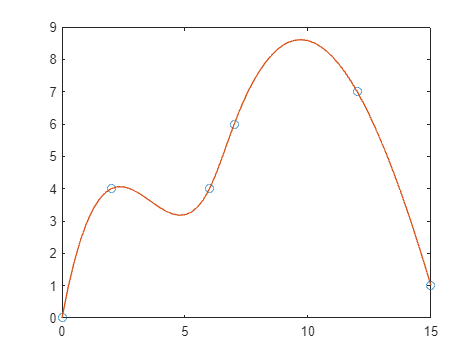


plot(x,y,'o',xx,yy)


yvalue = spline(x, y, 5)

yvalue = 3.1929

## TS7 - M8.1

Temperatura 

x = [595 623 761 849 989 1076 1146 1202 1382 1445 562]';
y = [2.12 3.12 14.4 30.6 80.3 131 186 240 489 604 868]';

% g(T)
M = [log(x) -1./x]

M =     6.3886   -0.0017
    6.4345   -0.0016
    6.6346   -0.0013
    6.7441   -0.0012
    6.8967   -0.0010
    6.9810   -0.0009
    7.0440   -0.0009
    7.0917   -0.0008
    7.2313   -0.0007
    7.2759   -0.0007


b = y; % - c1

A = M' * M

A =   513.2455   -0.0848
   -0.0848    0.0000


b1 = M' * b

b1 = 1.0e+04 *

    1.8243
   -0.0003



% Coeficientes de regresión
c = linsolve(A,b1)

coef = 1.0e+04 *

    0.0041
    3.3723



% Aproximación de k en T = 600


## TS7 - M8.2

Ajuste lineal 

## TS7 - M8.3

format long
% Datos proporcionados:
% Datos proporcionados:
K = [10; 15; 20; 20];
L = [12; 18; 12; 15];
F = [44624.0; 66936.0; 58881.8; 67317.3];

% Linearización de la ecuación a través de logaritmos:
logF = log(F);
logK = log(K);
logL = log(L);

% Construir la matriz de diseño:
X = [ones(size(logK)), logK, logL];

% Resolver para los coeficientes usando ecuaciones normales:
coeffs = (X'*X) \ (X'*logF);

alpha_cb = coeffs(2);
beta_cb = coeffs(3);

% Estimación de la producción para K=12 y L=25:
Faprox = exp(coeffs(1)) * 12^alpha_cb * 25^beta_cb;

% Función objetivo para el método de bisección:
objective = @(L_value) 45 - (3*L_value) + 3*L_value - Faprox;

% Método de bisección:
a = 4;
b = 8;
for i = 1:10
    c = (a+b)/2;
    if objective(a)*objective(c) < 0
        b = c;
    else
        a = c;
    end
end
L = (a+b)/2;

% Hallar el valor de K a partir de la restricción presupuestaria:
K = (45 - 3*L_val)/2;

% Mostrar resultados:
disp(['alpha_cb = ', num2str(alpha_cb)])

alpha_cb = 0.4


disp(['beta_cb = ', num2str(beta_cb)])

beta_cb = 0.6


disp(['Faprox = ', num2str(Faprox)])

Faprox = 74558.2552


disp(['L = %f', L])

L = 7.998


disp(['K = %f', K])

K = 10.5029


Tabla de diff div grado 2

function delta2=difdiv2(x,y)
    n = length(x);
    M = zeros(n);
    M(1:n,1) = y;

    for k = 1:n-1
        delta_x = x(k+1:n)-x(1:n-k);
        delta_y = diff(y)./delta_x;
        M(1:n-k,k+1) = delta_y;
        y=delta_y;
    end
    
    M = [x' M];
    
    delta2 = M(:,4);
end

Spline Natural

function S=splinenatural(X,Y)
    N=length(X)-1;
    H=diff(X);
    E=diff(Y)./H;
    diagprinc=2*(H(1:N-1)+H(2:N));
    diagsupinf=H(2:N-1);
    g0=0; gn=0;
    A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b=6*diff(E');
    g=A\b;
    g=[g0 g' gn ]
    for i=1:N
        S(i,1)=(g(i+1)-g(i))/(6*H(i));
        S(i,2)=g(i)/2;
        S(i,3)=E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4)=Y(i);
        xx=linspace(X(i),X(i+1),100);
        yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy)
        hold on
    end
    grid on
    hold off
end


b

function z=biseccion(f,a,b,Maxiter)
    c=(a+b)/2;
    error=(b-a)/2;
    z=[a b c f(a) f(b) f(c) error];
    for k=1:Maxiter
        if f(a)*f(c)<0
        b=c;
        else
        a=c;
        end
        c=(a+b)/2;
        error=(b-a)/2;
        z=[z;a b c f(a) f(b) f(c) error];
    end
    [row col] = size(z);
    fprintf('Se necesita %d iteraciones\n',(row-1));
end
